# ROBT403 HW3: Differential Drive Path Following by avoiding an obstacle using ANN

### **By Aigerim Keutayeva**

In this example, a differential drive robot navigates a waypoint using the Pure Pursuit algorithm while avoiding obstacles using the Vector Field Histogram algorithm.

The Map was created in Photoshop Editor in png format and converted to pbm format. To import map I used Navigation Toolbox functions.

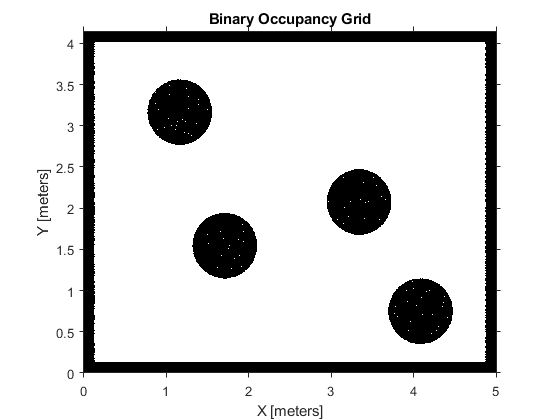

close all
clear
map1 = imread('test1.pbm');
map = robotics.BinaryOccupancyGrid(map1, 200);
show(map)

Next, the Visualizer2D ... Aikesha Super goi!

% create robot
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);
WRT = [R L];

% Angular velocity of a robot wheels
% wL = 1;
% wR = -0.5;
% [v,w] = forwardKinematics(dd,wL,wR)

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:40;        % Time array

% Initial conditions
initPose = [0.5;0.5;0] ;           % Initial pose (x y theta)
pose = initPose;  % Pose matrix
idx = 1;

## Create and Modify Binary Occupancy Grid

gjg

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,50); %50 number of points
lidar.maxRange = 5;

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.robotRadius = 0.5;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

## Path planning and following

% Create waypoints
waypoints = [0.5 0.5; 
              4.5 3.5];
idx = 1;

## Simulation loop

while((abs(waypoints(1)-initPose(1))>.1)||(abs(initPose(2)-waypoints(2))>.1))
    next_pose = [0; 0; 0];
    pose = [pose next_pose]; % concatenate next pose to the pose matrix
    
    % calculate the direction to target (degrees to understand easier)
    targetDir = rad2deg(atan2(waypoints(2)-initPose(2),...
                waypoints(1)-initPose(1)) - initPose(3));
    
    % make the direction circulat in -180 - 180 degrees
    if targetDir > 180
        targetDir = targetDir - 360;  
    elseif targetDir < -180
        targetDir =  360 + targetDir;
    end
    
    targetDir = ((targetDir+180)/(2*180)) - 0.5;
    
    % inputs from sensor in range 0 - 0.25m
    ranges = (lidar(initPose) - viz.robotRadius); 
    
    % normalize to 0.1 - 1 for ANN
    rangesN = (ranges+0.1)/0.4;
    
    % create ANN
    % inputs matrix --> [dir, CC, CR, CL, CRR, CLL]
    inputs = [targetDir, 1/rangesN(3), 1/rangesN(2),...
              1/rangesN(4), 1/rangesN(1), 1/rangesN(5)];
    
    % change NaN inputs to 0
    inputs (isnan(inputs)) = 0;
    
    % ANN
    weights = [-0.9, -0.15, 0, 0.35, 0, 0.5;  % left wheel
                0.9, -0.15, 0.35, 0, 0.5, 0]; % right wheel
             
    bias = 0.2;
    activation = (weights * inputs.') + bias;    
    leftW = activation(1)*30;
    rightW = activation(2)*30;
    
    % calc FK
    [v, y, w] = FK(WRT,leftW,rightW);
    
    % calculate the velocity of the robot relative to the map
    velocity = rtm([v; y; w], initPose);
    
    % calculate next pose
    pose(:,idx+1) = initPose + velocity * sampleTime;
    
    % move toward waypoint
    viz(pose(:,idx+1), waypoints, ranges)
    
    % iterate the counter and current pose variable
    idx = idx + 1;
    initPose = pose(:,idx);
end

Forward Kinematics and Roto-translation functions

function [v, y, w] = FK(robot, LW, RW)
    y = 0; % zero lateral velocity (for rtm)
    v = 0.5 * robot(1) * (LW + RW);
    w = (RW - LW) * robot(1)/robot(2);
end

function velocity = rtm(V, pose)
    angle = pose(3);
    velocity = [cos(angle) -sin(angle) 0; sin(angle) cos(angle)  0; 0 0 1]*V;
end

